# Actividad 1

**1) Implementar en un filtro FIR pasa bajos (ejemplo anterior) de largo M=51 (es decir orden N=50), frecuencia de corte fc=2400 Hz y frecuencia de muestreo fs=7200 Hz. **

clear; close all; clc;

M  = 51;   %cantidad de muestras
N  = M-1;  %Numero de muestras
fc = 2400; %Hz: frecuencia de corte.
fs = 7200; %Hz: frecuencia de muestreo.
Ts = 1/fs; %s:  tiempo de muestreo.
nfft=  8192; %numero de beans.

La respuesta en frecuencia de un filtro idea 1 constante ne la banda de paso, cero en el resto.

Si se obtiene la respuesta en el tiempo (n) se vé que infinita y no causal por lo que si uno quiere volverla causal y finita puede ventanear la señal en el tiempo (n).

Pero el resultado del ventaneo no es un filtro ideal, se hace presente el efecto gibs

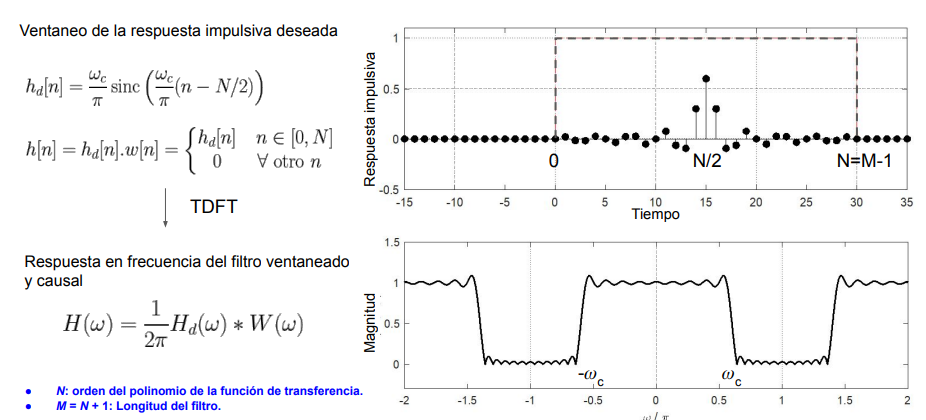

● Computar la respuesta impulsiva h(n)=hd(n).w(n) (usando la función sinc() ) 

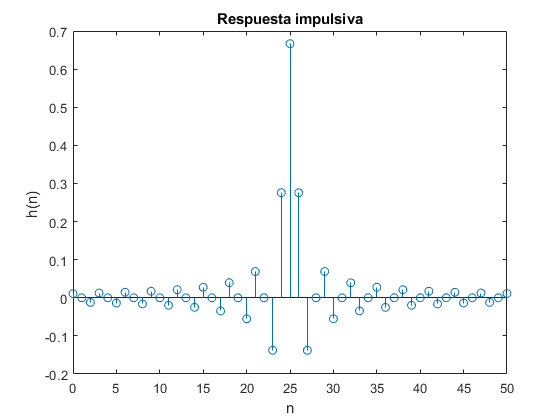

%El ventaneo es solo tomar n muestras de toda la señal.
%ventana.
n= 0:N; %ventaneo
%respuesta impulsiva del filtro
h= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );
%respuesta impulsiva ventaneada
RespImpulsiva= h(n, 2*pi*fc*Ts, N);

stem(n, RespImpulsiva)
title("Respuesta impulsiva"); ylabel("h(n) "); xlabel("n");

● Computar la respuesta en frecuencia (usando FFT de 8192 puntos) 

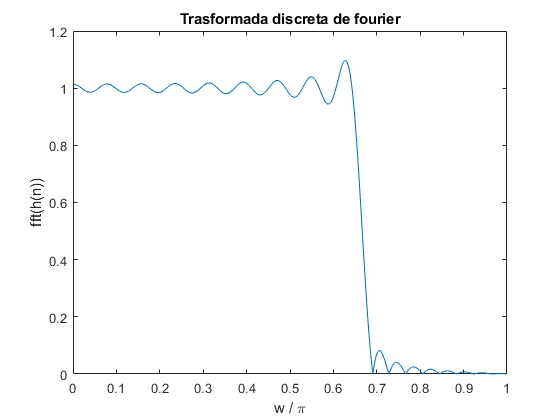

%puntos en frecuencia para el fft
w= linspace(0, 2*pi, nfft);
%transformada discreta e fourier.
H = fft(RespImpulsiva, nfft);

plot(w/pi, abs(H));
xlim([0, 1])
title("Trasformada discreta de fourier"); xlabel("w / \pi"); ylabel("fft(h(n))")

**2) Graficar en un mismo plot() el módulo de H(𝜔) para los filtros definidos con los siguientes órdenes: N={50, 100, 200, 500}. Medir ripple y transición.**


hold off;

for N = [50 100 200 500]
    disp(N)
    %ventana.
    n = 0:N;
    %respuesta impusiva.
    RespImpulsiva= h(n, 2*pi*fc*Ts, N);
    %Transformada de fourier
    H = fft(RespImpulsiva, nfft);
    
    figure(1)
    plot(w/pi, abs(H));
    grid on;
    hold on;
end

    50



   100



   200



   500



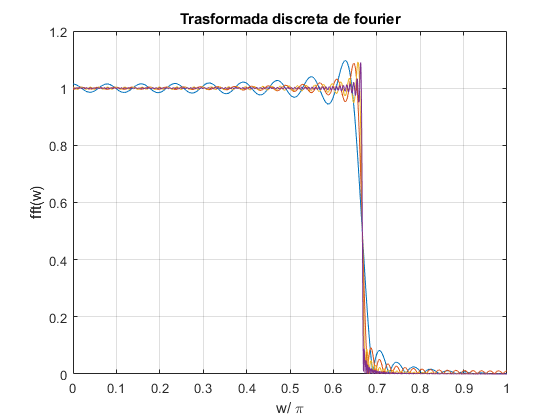

xlim([0, 1])
title("Trasformada discreta de fourier"); xlabel("w/ \pi"); ylabel("fft(w)")
hold off;

***los sobrepicos se mantienen constantes, y la banda de transicion disminuye a medida que aumenta el orden del filtro. osea a medida que la ventana es mas grande!***